
s = tf('s');

% create plant

P = tf([1],[1 1 0]);

[A,B,C,D] = ssdata(P);

% place eigenvalues at desired locations
psf = [-2 + 2*3^0.5*i, -2 - 2*3^0.5*i];

K =  place(A,B,psf);
% 
% check to see if the answer is correct

eig(A-B*K)

ans =   -2.0000 + 3.4641i
  -2.0000 - 3.4641i



% evaluate step response of system with state feedback.
% the transfer function is Tsf = c(sI-a+b*k)^(-1)b
figure(1)
clf
Tsf =  C/(s*eye(2) -A +B*K)*B

Tsf =
 
        1
  --------------
  s^2 + 4 s + 16
 
Continuous-time transfer function.



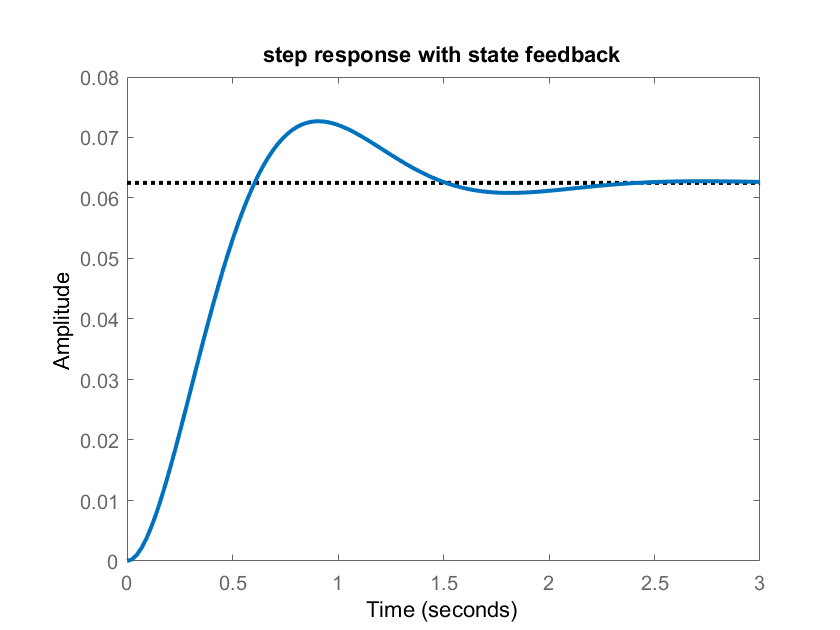

step(Tsf)
title('step response with state feedback')
set(findall(gcf,'type','line'),'linewidth',2)

% design observer  

pobs = [-1, -2]';

L =  place(A',C',pobs')';

eig(A-L*C)

ans =     -2
    -1


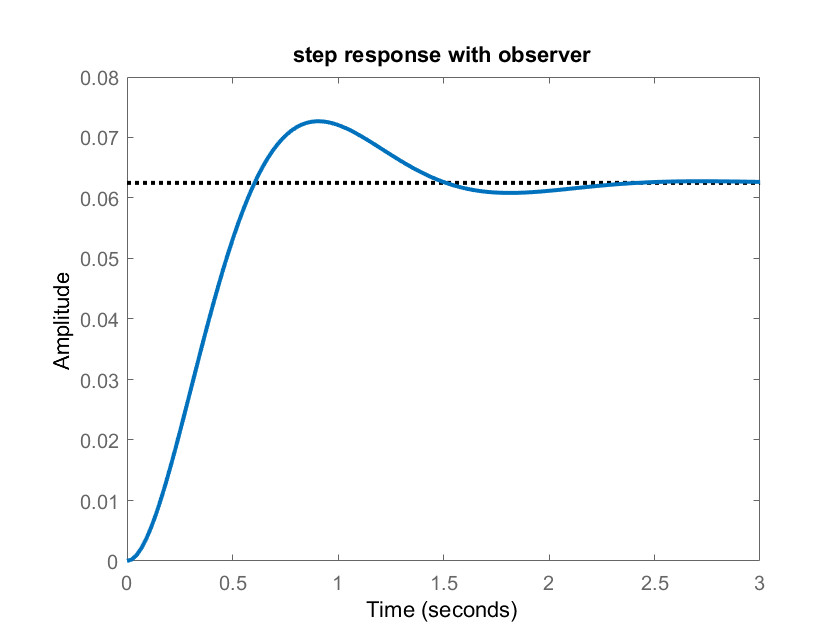


% evaluate the step response with the observer (should be same as without)

Abig =  [A - B*K B*K;zeros(2) A - L*C];
Bbig =  [B;zeros(2,1)];
Cbig =  [C zeros(1,2)];
Dbig =  0;

Tobs = ss(Abig,Bbig,Cbig,Dbig);
figure(2)
clf
step(Tobs)
title('step response with observer')
set(findall(gcf,'type','line'),'linewidth',2)

fprintf('------The expression is not related to x_hat----')

------The expression is not related to x_hat----

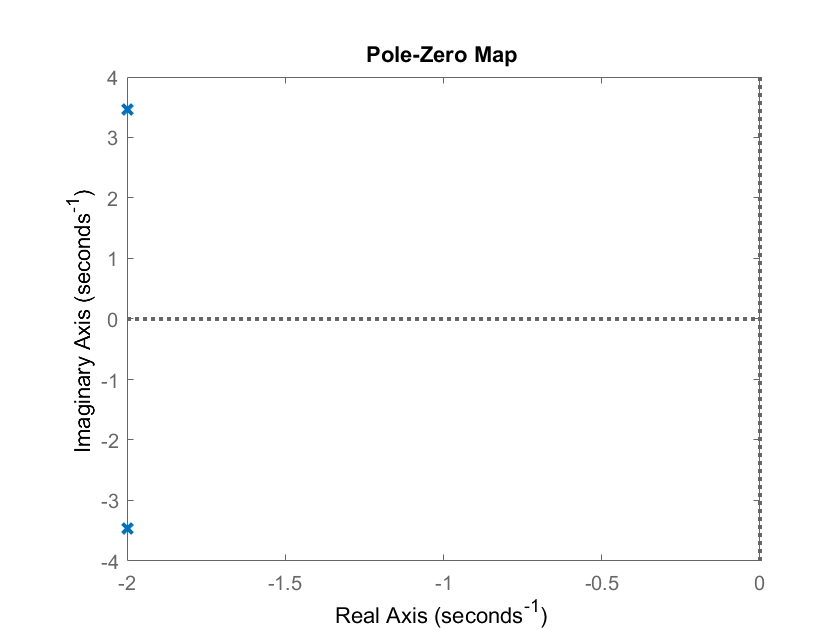


% check the poles and zeros of the transfer function from r to y
zeros_Tsf = tzero(Tsf);
poles_Tsf = pole(Tsf);
figure(3)
clf
pzmap(Tsf)
set(findall(gcf,'type','line'),'linewidth',2) 

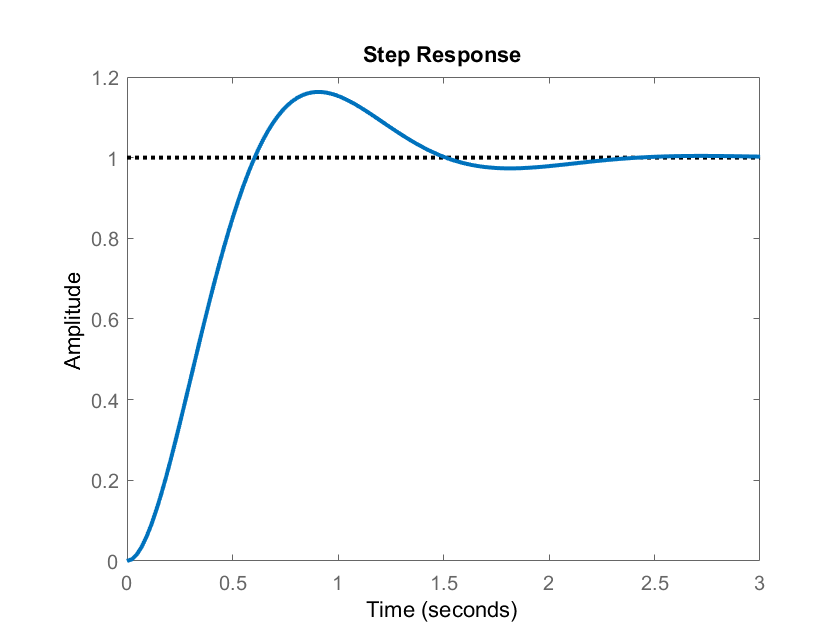

 

% normalize to achieve unity DC gain and check the step response

G =  1/dcgain(Tsf);

figure(4)
clf
step(Tsf*G)
set(findall(gcf,'type','line'),'linewidth',2)


% state space description of the observer based compensator, Cobs

A_Cobs =  A - B*K - L*C;

A_Cobs =    -4.0000  -16.0000
    1.0000   -2.0000


B_Cobs =  L;

B_Cobs =      0
     2


C_Cobs =  K;

C_Cobs =     3.0000   16.0000


D_Cobs =  0;

D_Cobs = 0


Cobs =  C_Cobs /(s*eye(2) - A_Cobs) * B_Cobs

Cobs =
 
    32 s + 32
  --------------
  s^2 + 6 s + 24
 
Continuous-time transfer function.



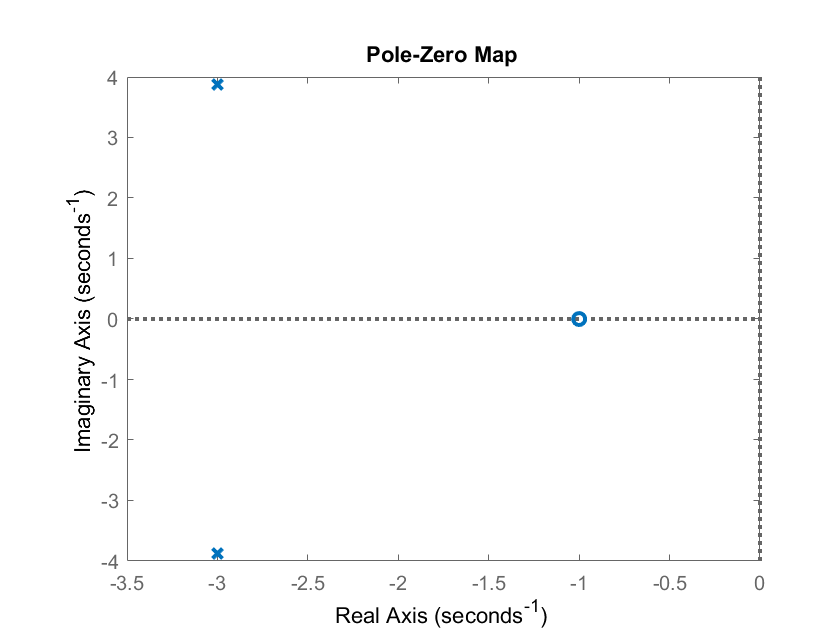



% check poles and zeros of observer based compensator
figure(5)
clf
pzmap(Cobs)
set(findall(gcf,'type','line'),'linewidth',2)

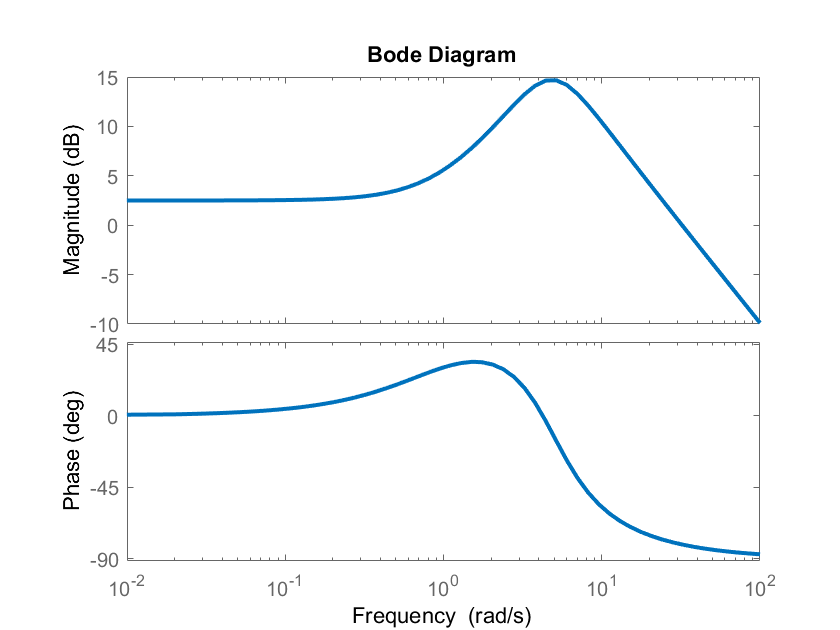


% check bode plot of observer based compensator
figure(6)
clf
bode(Cobs)
set(findall(gcf,'type','line'),'linewidth',2)

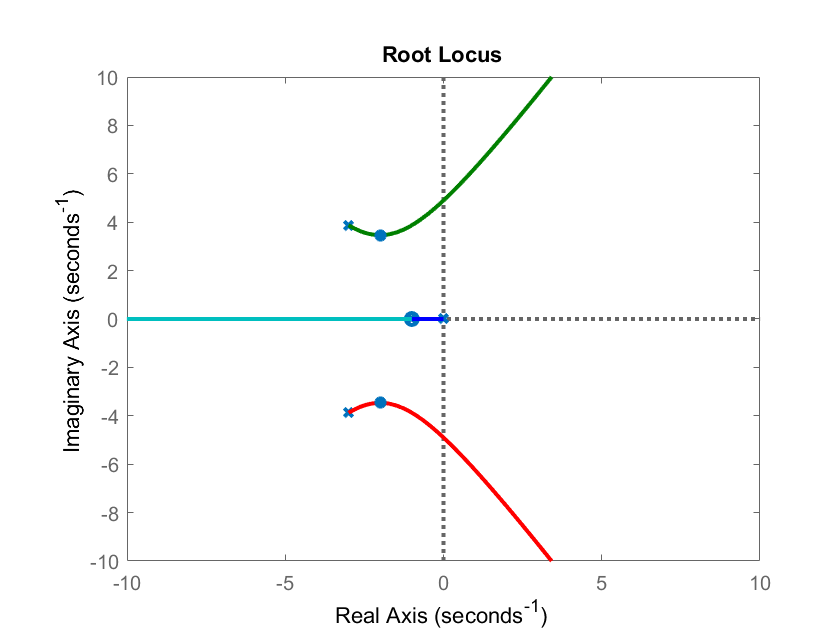


figure(7)
clf

Lobs = P*Cobs;

rlocus(Lobs)
hold on
plot(psf,'*')
hold off
axis([-10 10 -10 10])
set(findall(gcf,'type','line'),'linewidth',2)

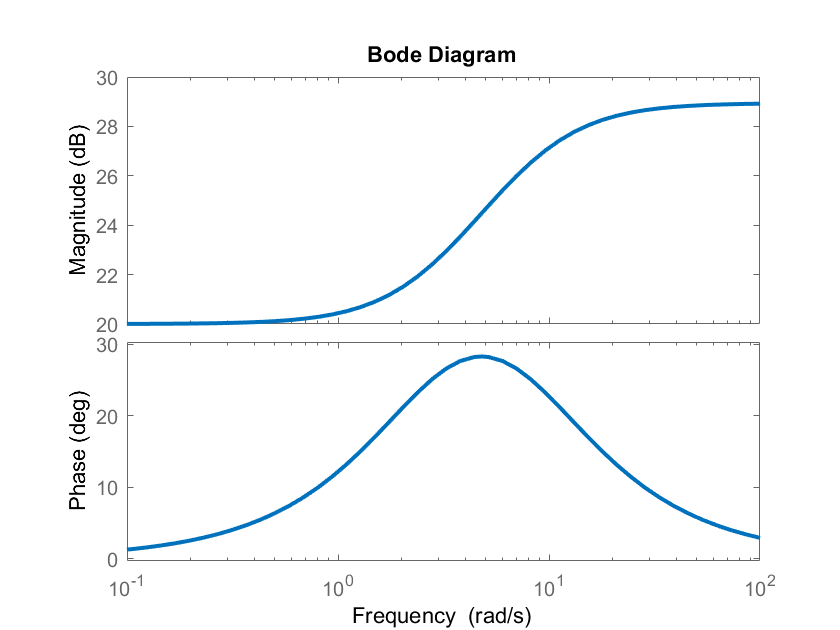


% now find a reduced order observer 
% use a realization of P with C = [1 0]

Ar = [-1 1;0 0];
Br = [0; 1];
Cr = [1 0];
Dr = 0;

A11 = Ar(1,1);A12 = Ar(1,2); A21 = Ar(2,1);A22 = Ar(2,2);
B1 = Br(1);B2 = Br(2);
Kr = place(Ar,Br,psf);
K1 = Kr(1);K2 = Kr(2);
pobsr = -5; % a rather arbitrary location
Lr  = place(A22,A12,pobsr);

Aroo = [A22-Lr*A12-(B2-Lr*B1)*K2];
Broo = (A22-Lr*A12)*Lr+(A21-Lr*A11)-(B2-Lr*B1)*(K1+K2*Lr);
Croo = K2;
Droo = (K1+K2*Lr);
Cobsr = ss(Aroo,Broo,Croo,Droo);

fiure(8)
clf
bode(Cobsr)
set(findall(gcf,'type','line'),'linewidth',2)

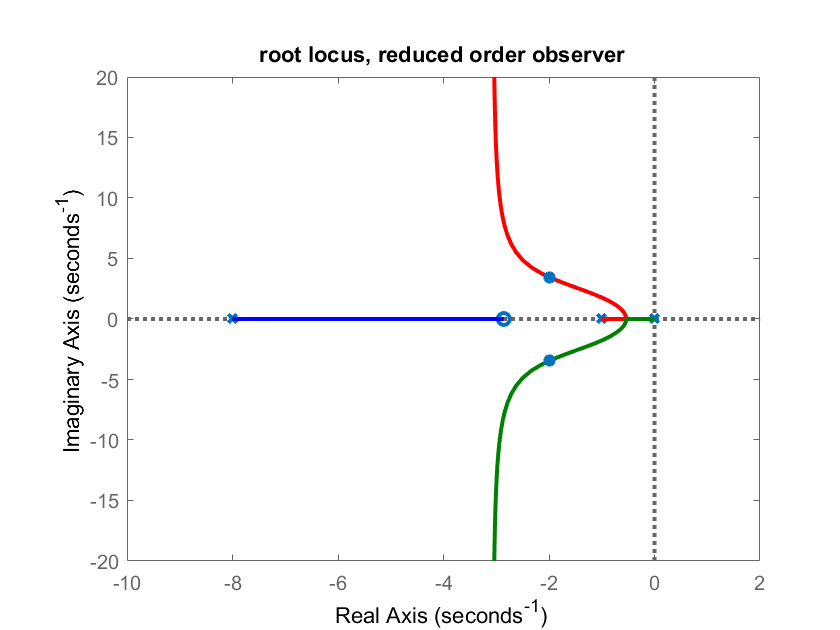


figure(9)
clf

Lobsr = P*Cobsr;
rlocus(Lobsr)
hold on
plot(psf,'*')
hold off
title('root locus, reduced order observer')
set(findall(gcf,'type','line'),'linewidth',2)